# Recursive Oscillators

A tool to hear the most common synthetic sinusoids.

## Preliminary Operations

These steps allow you to choose the desired oscillator among the most common ones. The application allows to select the desired angle as well, which will affect the k parameter.

The following oscillators are stored, and here you can observe the criteria each one has:

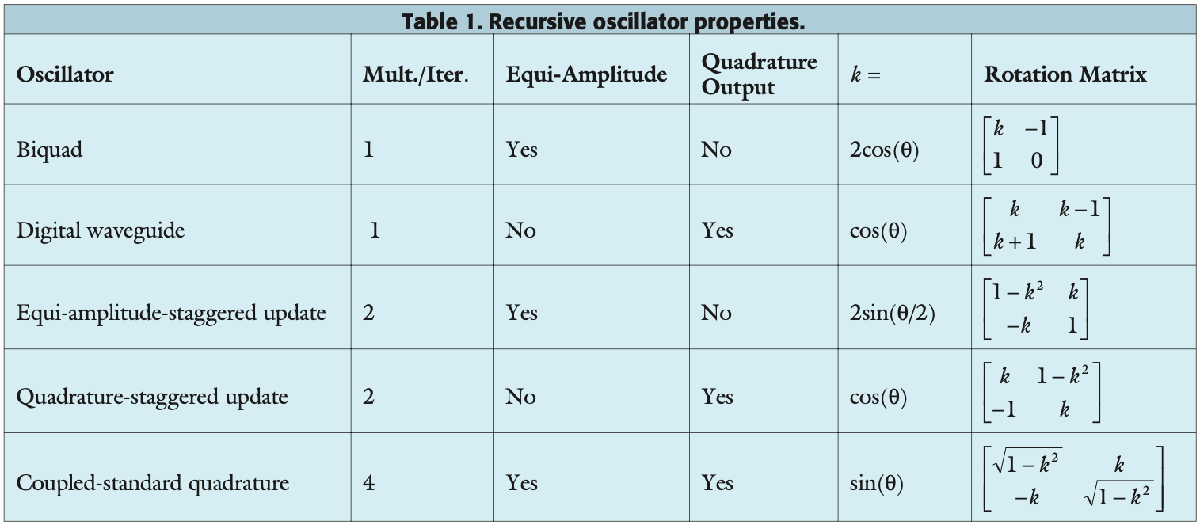

(credits: Clay S. Turner, "DSP Tips and Tricks - Recursive Discrete-Time Sinusoidal Oscillators")

#### Select a preferred value of the angle θ:

theta = 283.36;
%theta = (theta*pi)/90;

#### Select the desired oscillator:

A_bi_quad = [2*cos(theta), -1; 1, 0];
A_dig_wave = [cos(theta), cos(theta)-1; cos(theta)+1, cos(theta)];
A_ea_stagg = [1-(2*sin(theta/2))^2, 2*sin(theta/2); -2*sin(theta/2), 1];
A_quad_stagg = [cos(theta), 1-(cos(theta))^2; -1, cos(theta)];
A_couplestd_quad = [sqrt(1-(sin(theta))^2), sin(theta); -sin(theta), sqrt(1-(sin(theta))^2)];

Osc1 = A_dig_wave ;

#### Choose the initial state:

x1 =1;
x2 =0;

pos1 = [x1; x2];

% B is declared in order to reproduce sound
% B_short is much smaller than B in order to have a clear plot
B=4000;
B_short= 100;
Fs=2000; % for the sound reproduction

sign1 = zeros(2, B);

for i=1:B
    sign1(:, i) = Osc1*pos1;
    pos1 = sign1(:, i);
end 

## See the results!

The following figure shows the progress of the oscillator over time, expressed by the the state variables x1(n) and x2(n).

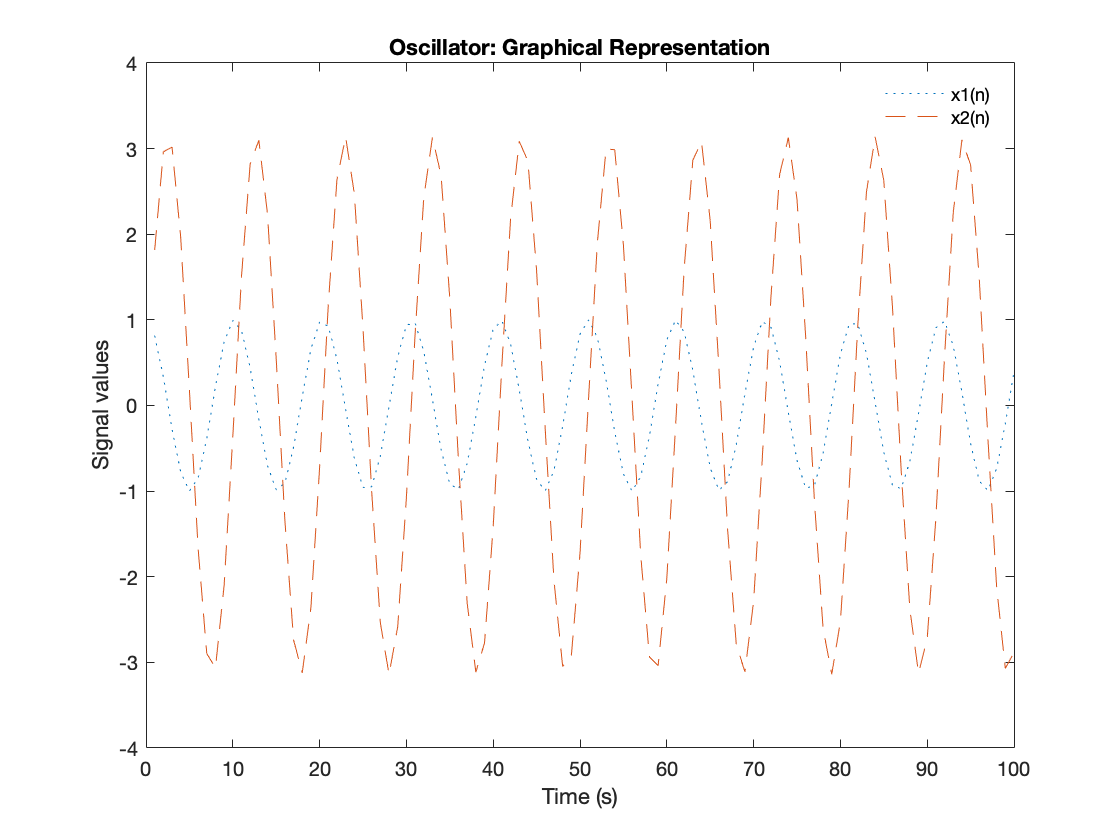

true;

close

% the ans is the boolean value of the tick, so that we can control the plot

if ans == 1
    plot(1:B_short, sign1(1, 1:B_short), ':')
end

title('Oscillator: Graphical Representation')
xlabel('Time (s)');
ylabel('Signal values')
% if ans == 1
%     legend('x1(n)')
% end
legend('boxoff')
hold on

true;
if ans == 1
    plot(1:B_short, sign1(2, 1:B_short), '--')
end
title('Oscillator: Graphical Representation')
xlabel('Time (s)');
ylabel('Signal values')
legend('x1(n)','x2(n)')
% if ans == 1
%     legend('x2(n)')
% end
legend('boxoff')

## Hear the results!

Press play in order to hear the oscillator as common synthesizers usually use.

 

soundsc(sign1, Fs)